# **DigitalTwin & Automation**

## **TEAM PROJECT**

### KAMP Injection Molding Machine ManufacturingData Diagnosis

Name:         Park Jeong Woo

                    Yoo Jin Soo

                    Hong Se Hyun

## **Outline**

**    1.    Problem & Data Description**

**    2.    Guidebook-Based Machine Learning**

**    3.    DTA/DLIP Lecture-Based Machine Learning**

**    4.    DTA/DLIP Lecture-Based Machine Learning with Sequential Feature Selection**

**    5.    DTA/DLIP Lecture-Based Machine Learning with PCA**

**    6.    Accuracy Compare & Model Evaluation**

**    7.    Flow Chart**

**    8.    Discussion & Conclusion**

**    9.    Reference**

# **1.    Problem & Data Description**

## **Introduce**

This project is about the defective diagnosis of windshield side molding of automobiles manufactured by gas injection molding.

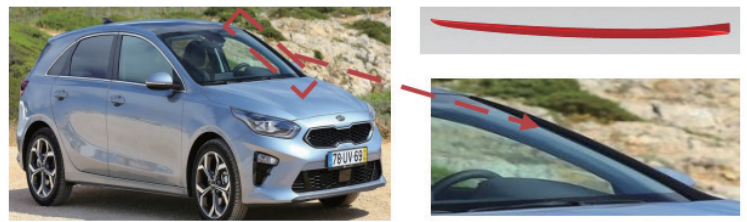

When gas injection molding is performed to produce windshield side molding, it is difficult to stop or control the process immediately at the time of occurrence of a defect.

It is important to control the amount of gas in this process because products having different thicknesses may shrink, distort, and sink.

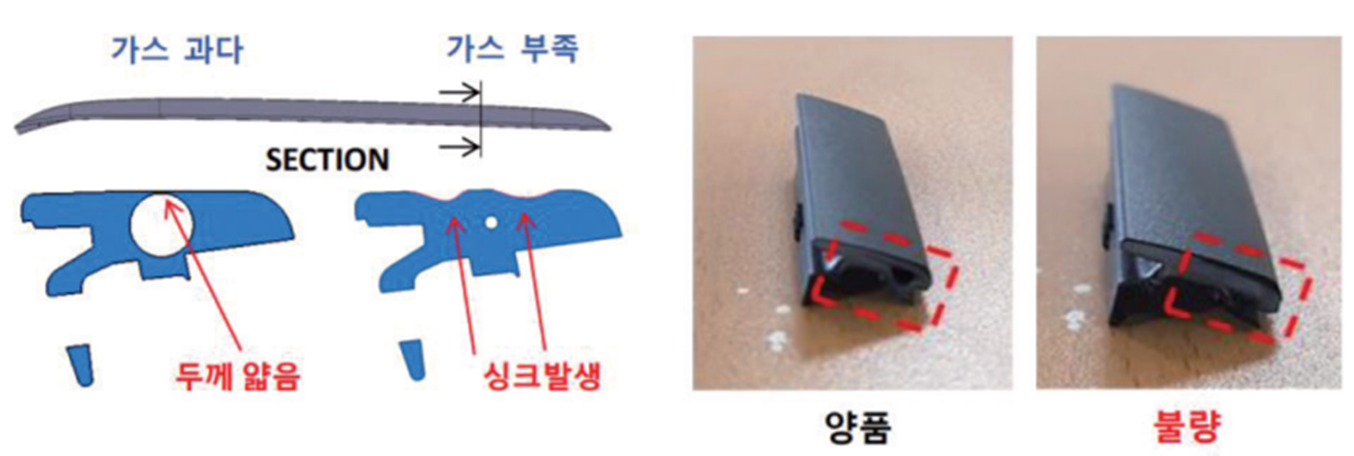

Therefore, a defective product is determined by comparing the temperature of the gas injected with the surface thickness.

Here, the temperature of the injected gas was confirmed through a thermal imaging camera.

For more information about this project, Read the Guidebook in KAMP, named **'「머신비전 AI 데이터셋」 분석실습 가이드북'.**

## **Dataset**

Download Machine Vision KAMP dataset : [Download here](https://www.kamp-ai.kr/front/dataset/AiDataDetail.jsp?AI_SEARCH=&page=1&DATASET_SEQ=6&EQUIP_SEL=&FILE_TYPE_SEL=&GUBUN_SEL=&WDATE_SEL=)

- Variable name used in the analysis : Temperature raw data of a [320x256] pixel thermal image, product thickness data

-  Data collecting : Training data was acquired by photographing the Injection Molding product with a thermal imaging camera within a certain time. Label data, thickness, was acquired by hand-write.

- Filename Extension : csv, json

- Number of data : 1,674 pieces

- Dataset Total Capacity : 450 MB

- Criteria for Normal/Abnormal products

    Normal products : 0.8mm < Section thickness < 1.5mm

    Abnormal products : Section thickness <= 0.8mm   OR   Section thickness >= 1.5mm

**    [Raw Image Data & Raw Label Data provided by KAMP]**

            left_data.csv

            left_label.json

            right_data.csv

            right_label.json

**    [Preprocessed Image Data & Preprocessed Label Data provided by KAMP]**

            2nd_process_left_data.csv

            2nd_process_left_label.json

            2nd_process_Right_data.csv

            2nd_process_Right_label.json

**    [Preprocessed Image Data - Data Processed for this project]**

            PreProcessed_Image_L_Data.csv

            PreProcessed_Image_R_Data.csv

Looking at Dataset, it is divided into Left Dataset and Right Dataset.

However, if you plot one Left Image Data with *imshow*, you can see Left Product and Right Product at the same time.

This means that two products are included in one image. However, even if the thickness of one of the left or right products is omitted in one image, the other side product may still be used.

Therefore, data files are separated into left and right datasets.

In other words, the thickness information may be left out because it is data input manually.

Therefore, it is true that Left and Right Products are visible in one image at the same time, but in some cases only the thickness information for Left Product remains.

The corresponding image for this case is used as Left Data and cannot be used as Right Data.

If both Left Product and Right Product thickness information exists, the image for this case can be used as Left Data and Right Data at the same time.

## Algorithm

#### **For Feature Extraction**

- Statistical Features

#### **For Feature Reduction/Selection Use only**

- Sequential Forward Selection

- PCA

#### **For Classification Use**

- SVM

- KNN

- Decision Tree

***Experiment***** Output**: Accuracy & Confusion Matrix

# **2.    Guidebook-Based Machine Learning**

### **Guidebook Flowchart**

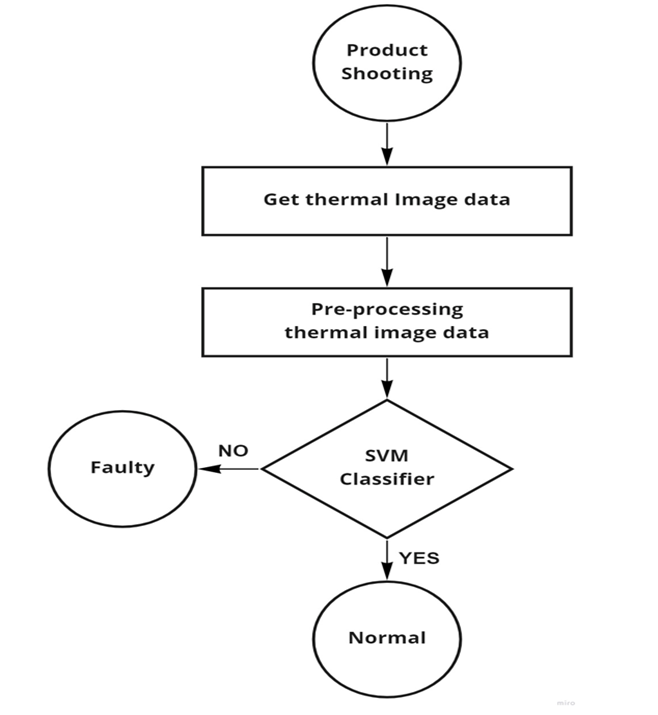

It is a step to figure out how Accuracy is when KNN, SVM, and Decision Tree Algorithm are applied to the 2nd pre-processed data presented in the guidebook.

In the guidebook, THRESH_BINARY and the Skeleton Method were applied to the thermal image of the injection molded product.

Subsequently, Skeleton Image was examined only 80 Pixels in one image data by obtaining only the Intensity value of the region of interest in rows 1 to 80.

2nd pre-processed data in which all these processes have been performed has already been provided by KAMP.

Therefore, in this step, the pre-processed KAMP data were received as it is, divided into Train Data and Test Data. And only the accuracy was compared by applying a learning model.

## 2.1 Load Data

close all;   clear;   clc;

addpath('Matlab_Functions');

% -------- Get Processed Train Data[GuideBook] ---------- %
L_guide_data  = load('Dataset_Machinevision\dataset\ProcessedData\2nd_process_left_data.csv');     % ProcessedData
R_guide_data  = load('Dataset_Machinevision\dataset\ProcessedData\2nd_process_right_data.csv');    % ProcessedData
% -------- Get Processed Label Data[GuideBook] ---------- %
L_guide_label = load('Dataset_Machinevision\dataset\ProcessedData\2nd_process_left_label.txt')';   % ProcessedData
R_guide_label = load('Dataset_Machinevision\dataset\ProcessedData\2nd_process_right_label.txt')';  % ProcessedData

## 2.2 Data Post-Processing

Define Global Table and Split Train/Test Data

### **Data Normalizing**

L_Guide_Normalized          = normalize(L_guide_data, 'range')

L_Guide_Normalized =     0.1974    0.1668    0.1252    0.0921    0.1572    0.0513    0.0433    0.0789    0.0899    0.0884    0.0572    0.0970    0.0959    0.0735    0.0606    0.0417    0.1010    0.1023    0.1085    0.1102    0.1155    0.1156    0.1165    0.1276    0.1383    0.1540    0.1578    0.1707    0.1816    0.1931    0.1968    0.2225    0.2225    0.3563    0.3695    0.3460    0.3748    0.3710    0.3661    0.3751    0.3708    0.3216    0.3286    0.3328    0.3477    0.3301    0.3540    0.3382    0.3528    0.3709
    0.2829    0.2150    0.1252    0.1714    0.1783    0.0593    0.0892    0.0839    0.0838    0.0713    0.1010    0.0916    0.0732    0.0588    0.1167    0.1039    0.0999    0.1046    0.1116    0.1062    0.1162    0.1199    0.1252    0.1314    0.1436    0.1508    0.1634    0.1766    0.1893    0.2055    0.2142    0.2262    0.2320    0.2359    0.2364    0.2277    0.2495    0.2515    0.2479    0.3901    0.4078    0.3535    0.3609    0.3671    0.3703    0.3774    0.3778    0.39

R_Guide_Normalized          = normalize(R_guide_data, 'range')

R_Guide_Normalized =     0.1974    0.1668    0.1252    0.0921    0.1572    0.0513    0.0433    0.0789    0.0899    0.0884    0.0572    0.0970    0.0959    0.0735    0.0606    0.0417    0.1010    0.1023    0.1085    0.1102    0.1155    0.1156    0.1165    0.1276    0.1383    0.1540    0.1578    0.1707    0.1816    0.1931    0.1968    0.2225    0.2225    0.3563    0.3695    0.3460    0.3748    0.3710    0.3661    0.3751    0.3708    0.3216    0.3286    0.3328    0.3477    0.3301    0.3540    0.3382    0.3528    0.3709
    0.2829    0.2150    0.1252    0.1714    0.1783    0.0593    0.0892    0.0839    0.0838    0.0713    0.1010    0.0916    0.0732    0.0588    0.1167    0.1039    0.0999    0.1046    0.1116    0.1062    0.1162    0.1199    0.1252    0.1314    0.1436    0.1508    0.1634    0.1766    0.1893    0.2055    0.2142    0.2262    0.2320    0.2359    0.2364    0.2277    0.2495    0.2515    0.2479    0.3901    0.4078    0.3535    0.3609    0.3671    0.3703    0.3774    0.3778    0.39

### **Left Dataset Global Table**

L_Guide_Feature_ = [L_Guide_Normalized L_guide_label];
L_Guide_Table    = array2table(L_Guide_Feature_);

L_Guide_Table.Properties.VariableNames{'L_Guide_Feature_81'} = 'Left Label Guide'

L_Guide_Table = 414×81 table
    L_Guide_Feature_1    L_Guide_Feature_2    L_Guide_Feature_3    L_Guide_Feature_4    L_Guide_Feature_5    L_Guide_Feature_6    L_Guide_Feature_7    L_Guide_Feature_8    L_Guide_Feature_9    L_Guide_Feature_10    L_Guide_Feature_11    L_Guide_Feature_12    L_Guide_Feature_13    L_Guide_Feature_14    L_Guide_Feature_15    L_Guide_Feature_16    L_Guide_Feature_17    L_Guide_Feature_18    L_Guide_Feature_19    L_Guide_Feature_20    L_Guide_Feature_21    L_Guide_Feature_22    L_Guide_Feature_23    L_Guide_Feature_24    L_Guide_Feature_25    L_Guide_Feature_26    L_Guide_Feature_27    L_Guide_Feature_28    L_Guide_Feature_29    L_Guide_Feature_30    L_Guide_Feature_31    L_Guide_Feature_32    L_Guide_Feature_33    L_Guide_Feature_34    L_Guide_Feature_35    L_Guide_Feature_36    L_Guide_Feature_37    L_Guide_Feature_38    L_Guide_Feature_39    L_Guide_Feature_40    L_Guide_Feature_41    L_Guide_Feature_42    L_Guide_Feature_43    L_Guide_Feature_44    L_Guide_

### **Right Dataset Global Table**

R_Guide_Feature_ = [R_Guide_Normalized R_guide_label];
R_Guide_Table    = array2table(R_Guide_Feature_);

R_Guide_Table.Properties.VariableNames{'R_Guide_Feature_81'} = 'Right Label Guide'

R_Guide_Table = 423×81 table
    R_Guide_Feature_1    R_Guide_Feature_2    R_Guide_Feature_3    R_Guide_Feature_4    R_Guide_Feature_5    R_Guide_Feature_6    R_Guide_Feature_7    R_Guide_Feature_8    R_Guide_Feature_9    R_Guide_Feature_10    R_Guide_Feature_11    R_Guide_Feature_12    R_Guide_Feature_13    R_Guide_Feature_14    R_Guide_Feature_15    R_Guide_Feature_16    R_Guide_Feature_17    R_Guide_Feature_18    R_Guide_Feature_19    R_Guide_Feature_20    R_Guide_Feature_21    R_Guide_Feature_22    R_Guide_Feature_23    R_Guide_Feature_24    R_Guide_Feature_25    R_Guide_Feature_26    R_Guide_Feature_27    R_Guide_Feature_28    R_Guide_Feature_29    R_Guide_Feature_30    R_Guide_Feature_31    R_Guide_Feature_32    R_Guide_Feature_33    R_Guide_Feature_34    R_Guide_Feature_35    R_Guide_Feature_36    R_Guide_Feature_37    R_Guide_Feature_38    R_Guide_Feature_39    R_Guide_Feature_40    R_Guide_Feature_41    R_Guide_Feature_42    R_Guide_Feature_43    R_Guide_Feature_44    R_Guide_

### Divide Data to TrainData and TestData

According to the split ratio presented in the Guidebook, Train Data was divided into 75% and Test Data was divided into 25%.

**TrainData 75%,   TestData 25%**

[Left_Guide_Train, Left_Guide_Test]    = Preprocessing_DataSplit(L_Guide_Table, 0.25);
[Right_Guide_Train, Right_Guide_Test]  = Preprocessing_DataSplit(R_Guide_Table, 0.25);

### Left Data Split

Left_Guide_Size          = size(Left_Guide_Train);
Left_Guide_FeatureNumber = Left_Guide_Size(2);

Left_Guide_Train_Data  = Left_Guide_Train(:,1:Left_Guide_FeatureNumber-1)

Left_Guide_Train_Data = 311×80 table
    L_Guide_Feature_1    L_Guide_Feature_2    L_Guide_Feature_3    L_Guide_Feature_4    L_Guide_Feature_5    L_Guide_Feature_6    L_Guide_Feature_7    L_Guide_Feature_8    L_Guide_Feature_9    L_Guide_Feature_10    L_Guide_Feature_11    L_Guide_Feature_12    L_Guide_Feature_13    L_Guide_Feature_14    L_Guide_Feature_15    L_Guide_Feature_16    L_Guide_Feature_17    L_Guide_Feature_18    L_Guide_Feature_19    L_Guide_Feature_20    L_Guide_Feature_21    L_Guide_Feature_22    L_Guide_Feature_23    L_Guide_Feature_24    L_Guide_Feature_25    L_Guide_Feature_26    L_Guide_Feature_27    L_Guide_Feature_28    L_Guide_Feature_29    L_Guide_Feature_30    L_Guide_Feature_31    L_Guide_Feature_32    L_Guide_Feature_33    L_Guide_Feature_34    L_Guide_Feature_35    L_Guide_Feature_36    L_Guide_Feature_37    L_Guide_Feature_38    L_Guide_Feature_39    L_Guide_Feature_40    L_Guide_Feature_41    L_Guide_Feature_42    L_Guide_Feature_43    L_Guide_Feature_44    

Left_Guide_Train_Label = Left_Guide_Train(:,Left_Guide_FeatureNumber)

Left_Guide_Train_Label = 311×1 table
    Left Label Guide
    ________________

           0        
           0        
           0        
           0        
           0        
           0        
           0        
           1        
           0        
           1        
           1        
           0        
           0        
           1        
           1        
           0        


Left_Guide_Test_Data   = Left_Guide_Test(:,1:Left_Guide_FeatureNumber-1)

Left_Guide_Test_Data = 103×80 table
    L_Guide_Feature_1    L_Guide_Feature_2    L_Guide_Feature_3    L_Guide_Feature_4    L_Guide_Feature_5    L_Guide_Feature_6    L_Guide_Feature_7    L_Guide_Feature_8    L_Guide_Feature_9    L_Guide_Feature_10    L_Guide_Feature_11    L_Guide_Feature_12    L_Guide_Feature_13    L_Guide_Feature_14    L_Guide_Feature_15    L_Guide_Feature_16    L_Guide_Feature_17    L_Guide_Feature_18    L_Guide_Feature_19    L_Guide_Feature_20    L_Guide_Feature_21    L_Guide_Feature_22    L_Guide_Feature_23    L_Guide_Feature_24    L_Guide_Feature_25    L_Guide_Feature_26    L_Guide_Feature_27    L_Guide_Feature_28    L_Guide_Feature_29    L_Guide_Feature_30    L_Guide_Feature_31    L_Guide_Feature_32    L_Guide_Feature_33    L_Guide_Feature_34    L_Guide_Feature_35    L_Guide_Feature_36    L_Guide_Feature_37    L_Guide_Feature_38    L_Guide_Feature_39    L_Guide_Feature_40    L_Guide_Feature_41    L_Guide_Feature_42    L_Guide_Feature_43    L_Guide_Feature_44    L

Left_Guide_Test_Label  = Left_Guide_Test(:,Left_Guide_FeatureNumber)

Left_Guide_Test_Label = 103×1 table
    Left Label Guide
    ________________

           0        
           0        
           0        
           0        
           0        
           0        
           1        
           1        
           1        
           0        
           1        
           0        
           0        
           1        
           1        
           1        


### Right Data Split

Right_Guide_Size           = size(Right_Guide_Train);
Right_Guide_FeatureNumber  = Right_Guide_Size(2);

Right_Guide_Train_Data   = Right_Guide_Train(:,1:Right_Guide_FeatureNumber-1)

Right_Guide_Train_Data = 318×80 table
    R_Guide_Feature_1    R_Guide_Feature_2    R_Guide_Feature_3    R_Guide_Feature_4    R_Guide_Feature_5    R_Guide_Feature_6    R_Guide_Feature_7    R_Guide_Feature_8    R_Guide_Feature_9    R_Guide_Feature_10    R_Guide_Feature_11    R_Guide_Feature_12    R_Guide_Feature_13    R_Guide_Feature_14    R_Guide_Feature_15    R_Guide_Feature_16    R_Guide_Feature_17    R_Guide_Feature_18    R_Guide_Feature_19    R_Guide_Feature_20    R_Guide_Feature_21    R_Guide_Feature_22    R_Guide_Feature_23    R_Guide_Feature_24    R_Guide_Feature_25    R_Guide_Feature_26    R_Guide_Feature_27    R_Guide_Feature_28    R_Guide_Feature_29    R_Guide_Feature_30    R_Guide_Feature_31    R_Guide_Feature_32    R_Guide_Feature_33    R_Guide_Feature_34    R_Guide_Feature_35    R_Guide_Feature_36    R_Guide_Feature_37    R_Guide_Feature_38    R_Guide_Feature_39    R_Guide_Feature_40    R_Guide_Feature_41    R_Guide_Feature_42    R_Guide_Feature_43    R_Guide_Feature_44   

Right_Guide_Train_Label  = Right_Guide_Train(:,Right_Guide_FeatureNumber)

Right_Guide_Train_Label = 318×1 table
    Right Label Guide
    _________________

            1        
            1        
            1        
            1        
            1        
            1        
            1        
            1        
            1        
            1        
            1        
            0        
            0        
            1        
            0        
            0        


Right_Guide_Test_Data    = Right_Guide_Test(:,1:Right_Guide_FeatureNumber-1)

Right_Guide_Test_Data = 105×80 table
    R_Guide_Feature_1    R_Guide_Feature_2    R_Guide_Feature_3    R_Guide_Feature_4    R_Guide_Feature_5    R_Guide_Feature_6    R_Guide_Feature_7    R_Guide_Feature_8    R_Guide_Feature_9    R_Guide_Feature_10    R_Guide_Feature_11    R_Guide_Feature_12    R_Guide_Feature_13    R_Guide_Feature_14    R_Guide_Feature_15    R_Guide_Feature_16    R_Guide_Feature_17    R_Guide_Feature_18    R_Guide_Feature_19    R_Guide_Feature_20    R_Guide_Feature_21    R_Guide_Feature_22    R_Guide_Feature_23    R_Guide_Feature_24    R_Guide_Feature_25    R_Guide_Feature_26    R_Guide_Feature_27    R_Guide_Feature_28    R_Guide_Feature_29    R_Guide_Feature_30    R_Guide_Feature_31    R_Guide_Feature_32    R_Guide_Feature_33    R_Guide_Feature_34    R_Guide_Feature_35    R_Guide_Feature_36    R_Guide_Feature_37    R_Guide_Feature_38    R_Guide_Feature_39    R_Guide_Feature_40    R_Guide_Feature_41    R_Guide_Feature_42    R_Guide_Feature_43    R_Guide_Feature_44    

Right_Guide_Test_Label   = Right_Guide_Test(:,Right_Guide_FeatureNumber)

Right_Guide_Test_Label = 105×1 table
    Right Label Guide
    _________________

            1        
            1        
            0        
            1        
            0        
            1        
            0        
            0        
            0        
            1        
            1        
            1        
            1        
            1        
            1        
            0        


## 2.3 Classification Machine Learning

### Classification Machine Learning about LEFT dataset

KNN - SVM - TREE

k = 3

Knn_CrossValication_Error = 0.1061

Knn_Train_Loss = 0.0482

Knn_Test_Loss = 0.0688

SVM_CrossValication_Error = 0.1961

SVM_Train_Loss = 0

SVM_Test_Loss = 0.1682

Tree_CrossValication_Error = 0.1158

Tree_Train_Loss = 0.0193

Tree_Test_Loss = 0.1600

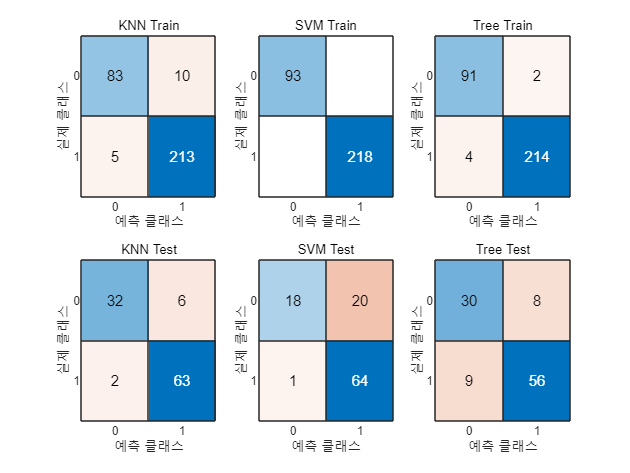

[Knn_Guide_Test_Loss_L, SVM_Guide_Test_Loss_L, Tree_Guide_Test_Loss_L] = KNN_SVM_TREE(Left_Guide_Train_Data, Left_Guide_Train_Label, Left_Guide_Test_Data, Left_Guide_Test_Label, 5);

### Classification Machine Learning about LEFT dataset

KNN - SVM - TREE

k = 3

Knn_CrossValication_Error = 0.0535

Knn_Train_Loss = 0.0252

Knn_Test_Loss = 0.0470

SVM_CrossValication_Error = 0.0818

SVM_Train_Loss = 0

SVM_Test_Loss = 0.1262

Tree_CrossValication_Error = 0.0660

Tree_Train_Loss = 0.0157

Tree_Test_Loss = 0.0690

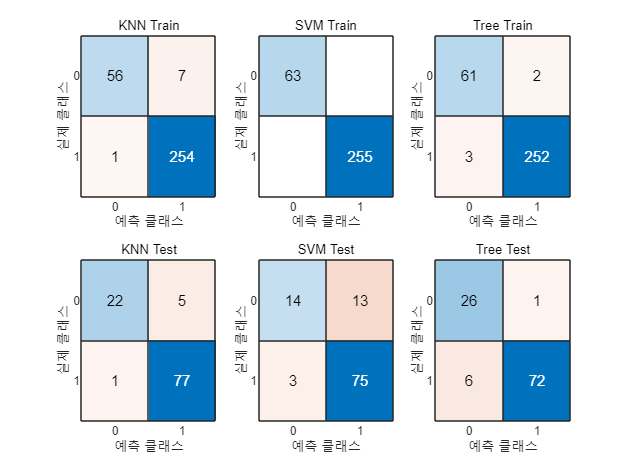

[Knn_Guide_Test_Loss_R, SVM_Guide_Test_Loss_R, Tree_Guide_Test_Loss_R] = KNN_SVM_TREE(Right_Guide_Train_Data, Right_Guide_Train_Label, Right_Guide_Test_Data, Right_Guide_Test_Label, 5);

## 2.4 Compare Accuracy

Classification Machine Learning Result about LEFT and RIGHT dataset.

Data Pre-processing was implemented and provided by KAMP. 

ColumnIndex_L                        = 'GuideBook_Accuracy_L';
ColumnIndex_R                        = 'GuideBook_Accuracy_R';
[Accuracy_Table_Guide_L, Accuracy_Table_Guide_R] = Evaluation_Accuracy(Knn_Guide_Test_Loss_L, SVM_Guide_Test_Loss_L, Tree_Guide_Test_Loss_L, ColumnIndex_L, Knn_Guide_Test_Loss_R, SVM_Guide_Test_Loss_R, Tree_Guide_Test_Loss_R, ColumnIndex_R);

Accuracy_Guidebook_Table = [Accuracy_Table_Guide_L Accuracy_Table_Guide_R]

Accuracy_Guidebook_Table = 3×2 table
            GuideBook_Accuracy_L    GuideBook_Accuracy_R
            ____________________    ____________________

    KNN            93.122                  95.303       
    SVM            83.183                  87.377       
    Tree           83.999                  93.098       


# **3.    DTA/DLIP Lecture-Based Machine Learning**

It is a step to figure out the Accuracy when KNN, SVM, and Decision Tree Algorithm are applied after extracting appropriate features through image processing for raw data presented in the guidebook.

This includes the Feature Reduction process.

Therefore, each Accuracy for 'Before Reduction', 'After SFS', 'After PCA' was compared to the Accuracy learned from the pre-processed data provided by KAMP.

By making the most of what we learned during this semester, we applied THRESH_BINARY and CONTOUR to thermal image to bring only the Intensity values of the area of interest.

This process was conducted using Python OpenCV in the Jupyter, and the processed data were imported into Matlab to perform the Feature Extraction and Feature Selection processes.

However, in the case of Label Data, since it is not Image Processing, it was transformed into Binary Data through a data pre-processing on Matlab.

## 3.1 Load Data

% -------- Get Processed Train Data[Pre-Processed by Python, Pre-processing in our own way] ---------- %
L_data = load('Python_Jupyter_ImageProcessing\PreProcessed_Image_L_Data.csv');  % ProcessedData
R_data = load('Python_Jupyter_ImageProcessing\PreProcessed_Image_R_Data.csv');  % ProcessedData

% -------- Get Law Label Data[Label data processing will proceed later]  ---------- %
L_label_unprocessed = load('Dataset_Machinevision\dataset\RawData\left_label.txt')';   % ProcessedData
R_label_unprocessed = load('Dataset_Machinevision\dataset\RawData\right_label.txt')';  % ProcessedData

## 3.2 Data Pre-Processing

### **Label Data Pre-Processing**

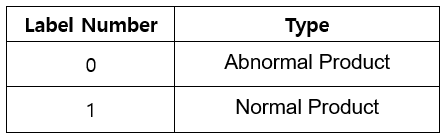

[L_label] = Preprocessing_Labelling(L_label_unprocessed);
[R_label] = Preprocessing_Labelling(R_label_unprocessed);

### **Get BreakPoint**

Get the data column index we need to extract features from 2000 columns

[L_breakpoint] = Preprocessing_BreakPoint(L_data);
[R_breakpoint] = Preprocessing_BreakPoint(R_data);

## 3.3 Make Features

### Reason for not using the RMS value

RMS is a method calculating for frequency data such as vibration signals. The RMS value was not used because the data we have is Image Intensity Data.

For the same reason, other statistical features derived from RMS, such as Crest Factor, Shape Factor, and Impulse Factor, were not used.

### The meaning of each feature

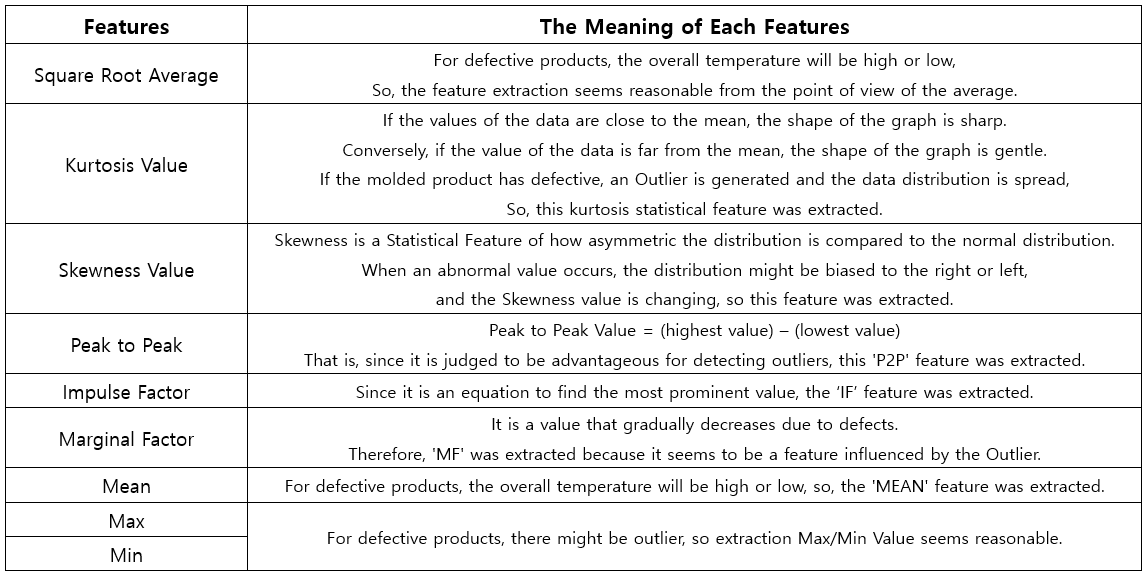

ColumnIndex =  ["SRA", "KV", "SK", "P2P","IF", "MF", "MEAN", "MAX", "MIN"];

[L_data_FeatureTable] = Preprocessing_GetFeatures(L_data, L_breakpoint, ColumnIndex)

L_data_FeatureTable = 414×9 table
    L_SRA      L_KV       L_SK       L_P2P     L_IF       L_MF     L_MEAN    L_MAX    L_MIN
    ______    ______    _________    _____    _______    ______    ______    _____    _____

    49.599    3.5868     -0.33279    31.75    0.63779    1.2853    49.781    63.75     32  
    49.604    3.5082     -0.36232    31.75     0.6377    1.2852    49.789    63.75     32  
    49.723    3.5754     -0.36677    31.75    0.63627    1.2821      49.9    63.75     32  
    49.519     3.322     -0.35431    31.75    0.63856    1.2874    49.721    63.75     32  
    49.836    3.5099     -0.33424    31.75    0.63479    1.2792    50.017    63.75     32  
    49.971     3.605     -0.23404    31.75    0.63348    1.2757     50.12    63.75     32  
    49.609     3.475     -0.24631    31.75    0.63801     1.285    49.764    63.75     32  
     49.53    3.3759     -0.24529    31.75    0.63886    1.2871    49.698    63.75     32  
    49.865    3.4736     -0.33552    31.75   

[R_data_FeatureTable] = Preprocessing_GetFeatures(R_data, R_breakpoint, ColumnIndex)

R_data_FeatureTable = 423×9 table
    L_SRA      L_KV       L_SK      L_P2P     L_IF       L_MF     L_MEAN    L_MAX    L_MIN
    ______    ______    ________    _____    _______    ______    ______    _____    _____

    49.721    2.0208    0.094991     17.5    0.35118    1.1766    49.832     58.5     41  
    50.014    2.0088     0.10189       18    0.35905    1.1797    50.133       59     41  
    49.653    2.0244    0.050586    17.25    0.34664    1.1732    49.764    58.25     41  
    49.867    2.0119     0.10179     17.5    0.35018    1.1731    49.975     58.5     41  
     49.84    2.0342    0.090662       17     0.3404    1.1637    49.941       58     41  
    49.967    2.0157     0.12918     17.5     0.3495    1.1708    50.072     58.5     41  
    49.662    2.0305    0.071358    17.25    0.34661    1.1729    49.768    58.25     41  
    49.833    2.0094    0.086694    17.25    0.34541    1.1689     49.94    58.25     41  
    49.902    2.0084     0.10135     17.5    0.34992   

L_label_Table   = array2table(L_label, 'VariableNames',"Left Label")

L_label_Table = 414×1 table
    Left Label
    __________

        0     
        0     
        0     
        0     
        0     
        0     
        0     
        0     
        0     
        0     
        0     
        1     
        0     
        1     
        1     
        0     


R_label_Table   = array2table(R_label, 'VariableNames',"Right Label")

R_label_Table = 423×1 table
    Right Label
    ___________

         1     
         1     
         1     
         1     
         1     
         1     
         1     
         1     
         1     
         1     
         1     
         1     
         1     
         0     
         1     
         0     


### **Data Normalizing**

L_data_FeatureTable_Normalized = normalize(L_data_FeatureTable, 'range')

L_data_FeatureTable_Normalized = 414×9 table
     L_SRA      L_KV       L_SK       L_P2P      L_IF       L_MF      L_MEAN      L_MAX     L_MIN
    _______    _______    _______    _______    _______    _______    _______    _______    _____

    0.58606    0.85758     0.4735          1    0.98874    0.95535    0.58738          1      0  
    0.58685     0.8212    0.44802          1    0.98851    0.95471    0.58866          1      0  
    0.60836    0.85228    0.44418          1      0.985    0.93724    0.60806          1      0  
    0.57151    0.73498    0.45493          1    0.99065    0.96723    0.57691          1      0  
    0.62881    0.82197    0.47224          1    0.98135     0.9207    0.62829          1      0  
     0.6531    0.86602    0.55867          1    0.97812    0.90115     0.6463          1      0  
    0.58778    0.80581    0.54808          1    0.98927    0.95395    0.58447          1      0  
    0.57361    0.75993    0.54896          1    0.99137    0.96551    0.

R_data_FeatureTable_Normalized = normalize(R_data_FeatureTable, 'range')

R_data_FeatureTable_Normalized = 423×9 table
     L_SRA       L_KV       L_SK       L_P2P      L_IF       L_MF      L_MEAN      L_MAX     L_MIN
    _______    ________    _______    _______    _______    _______    _______    _______    _____

    0.59855    0.059941     0.8251    0.38043    0.35287    0.42089    0.60207      0.625      1  
    0.64147    0.054022    0.83157    0.40217    0.37025    0.43604    0.64565    0.66071      1  
    0.58848    0.061733    0.78346    0.36957    0.34282    0.40432    0.59219    0.60714      1  
    0.61991    0.055543    0.83148    0.38043    0.35065    0.40419    0.62276      0.625      1  
      0.616    0.066602    0.82104     0.3587    0.32903    0.35845    0.61794    0.58929      1  
    0.63467    0.057397    0.85717    0.38043    0.34914     0.3927    0.63687      0.625      1  
    0.58988     0.06476    0.80294    0.36957    0.34275    0.40322    0.59288    0.60714      1  
    0.61492    0.054314    0.81732    0.36957    0.34011    0.3

### **Global Table [Feature | Label Combined Table]**

L_data_FeatureLabelTable = [L_data_FeatureTable_Normalized L_label_Table]

L_data_FeatureLabelTable = 414×10 table
     L_SRA      L_KV       L_SK       L_P2P      L_IF       L_MF      L_MEAN      L_MAX     L_MIN    Left Label
    _______    _______    _______    _______    _______    _______    _______    _______    _____    __________

    0.58606    0.85758     0.4735          1    0.98874    0.95535    0.58738          1      0          0     
    0.58685     0.8212    0.44802          1    0.98851    0.95471    0.58866          1      0          0     
    0.60836    0.85228    0.44418          1      0.985    0.93724    0.60806          1      0          0     
    0.57151    0.73498    0.45493          1    0.99065    0.96723    0.57691          1      0          0     
    0.62881    0.82197    0.47224          1    0.98135     0.9207    0.62829          1      0          0     
     0.6531    0.86602    0.55867          1    0.97812    0.90115     0.6463          1      0          0     
    0.58778    0.80581    0.54808          1    0.98927    0.95

R_data_FeatureLabelTable = [R_data_FeatureTable_Normalized R_label_Table]

R_data_FeatureLabelTable = 423×10 table
     L_SRA       L_KV       L_SK       L_P2P      L_IF       L_MF      L_MEAN      L_MAX     L_MIN    Right Label
    _______    ________    _______    _______    _______    _______    _______    _______    _____    ___________

    0.59855    0.059941     0.8251    0.38043    0.35287    0.42089    0.60207      0.625      1           1     
    0.64147    0.054022    0.83157    0.40217    0.37025    0.43604    0.64565    0.66071      1           1     
    0.58848    0.061733    0.78346    0.36957    0.34282    0.40432    0.59219    0.60714      1           1     
    0.61991    0.055543    0.83148    0.38043    0.35065    0.40419    0.62276      0.625      1           1     
      0.616    0.066602    0.82104     0.3587    0.32903    0.35845    0.61794    0.58929      1           1     
    0.63467    0.057397    0.85717    0.38043    0.34914     0.3927    0.63687      0.625      1           1     
    0.58988     0.06476    0.80294    0.36957  

## 3.4 Data Post-Processing

### Divide Data to TrainData and TestData

TrainData 75%,   TestData 25%

[Left_Train, Left_Test]   = Preprocessing_DataSplit(L_data_FeatureLabelTable, 0.25);
[Right_Train, Right_Test] = Preprocessing_DataSplit(R_data_FeatureLabelTable, 0.25);

### Left Data Split

Left_Size = size(Left_Train);
Left_FeatureNumber = Left_Size(2);

Left_Train_Data  = Left_Train(:,1:Left_FeatureNumber-1)

Left_Train_Data = 311×9 table
     L_SRA      L_KV       L_SK       L_P2P      L_IF       L_MF      L_MEAN      L_MAX     L_MIN
    _______    _______    _______    _______    _______    _______    _______    _______    _____

    0.58606    0.85758     0.4735          1    0.98874    0.95535    0.58738          1      0  
    0.58685     0.8212    0.44802          1    0.98851    0.95471    0.58866          1      0  
    0.60836    0.85228    0.44418          1      0.985    0.93724    0.60806          1      0  
    0.57151    0.73498    0.45493          1    0.99065    0.96723    0.57691          1      0  
     0.6531    0.86602    0.55867          1    0.97812    0.90115     0.6463          1      0  
    0.58778    0.80581    0.54808          1    0.98927    0.95395    0.58447          1      0  
    0.61258    0.72747    0.59479          1    0.98489    0.93381    0.60865          1      0  
    0.61553    0.77378    0.46691          1    0.98386    0.93142    0.61436          

Left_Train_Label = Left_Train(:,Left_FeatureNumber)

Left_Train_Label = 311×1 table
    Left Label
    __________

        0     
        0     
        0     
        0     
        0     
        0     
        0     
        1     
        0     
        1     
        1     
        1     
        1     
        1     
        1     
        1     


Left_Test_Data  = Left_Test(:,1:Left_FeatureNumber-1)

Left_Test_Data = 103×9 table
     L_SRA      L_KV       L_SK       L_P2P      L_IF       L_MF      L_MEAN      L_MAX     L_MIN
    _______    _______    _______    _______    _______    _______    _______    _______    _____

    0.62881    0.82197    0.47224          1    0.98135     0.9207    0.62829          1      0  
    0.57361    0.75993    0.54896          1    0.99137    0.96551    0.57295          1      0  
    0.63402    0.80515    0.47114          1    0.98057    0.91649    0.63267          1      0  
    0.59401    0.74808    0.59978          1    0.98798    0.94888    0.59159          1      0  
    0.64935    0.20652          1    0.49398    0.46383    0.73384    0.63559    0.87234      1  
    0.60706    0.71638    0.47241          1    0.98483    0.93829    0.60901          1      0  
    0.66649    0.85252    0.40892          1    0.97491    0.89042    0.66425          1      0  
    0.68253    0.73025    0.59851          1    0.97304    0.87761    0.67479          1

Left_Test_Label = Left_Test(:,Left_FeatureNumber)

Left_Test_Label = 103×1 table
    Left Label
    __________

        0     
        0     
        0     
        0     
        1     
        0     
        0     
        0     
        0     
        0     
        1     
        1     
        1     
        0     
        0     
        0     


### Right Data Split

Right_Size = size(Right_Train);
Right_FeatureNumber = Right_Size(2);

Right_Train_Data  = Right_Train(:,1:Right_FeatureNumber-1)

Right_Train_Data = 318×9 table
     L_SRA       L_KV       L_SK       L_P2P      L_IF       L_MF      L_MEAN      L_MAX     L_MIN
    _______    ________    _______    _______    _______    _______    _______    _______    _____

    0.59855    0.059941     0.8251    0.38043    0.35287    0.42089    0.60207      0.625      1  
    0.58848    0.061733    0.78346    0.36957    0.34282    0.40432    0.59219    0.60714      1  
    0.61991    0.055543    0.83148    0.38043    0.35065    0.40419    0.62276      0.625      1  
    0.63467    0.057397    0.85717    0.38043    0.34914     0.3927    0.63687      0.625      1  
    0.58988     0.06476    0.80294    0.36957    0.34275    0.40322    0.59288    0.60714      1  
    0.61492    0.054314    0.81732    0.36957    0.34011    0.38369    0.61781    0.60714      1  
    0.62505    0.053793    0.83106    0.38043    0.35009    0.40018      0.628      0.625      1  
    0.62215    0.065362    0.80957    0.38043    0.35043    0.40244    0.6247

Right_Train_Label = Right_Train(:,Right_FeatureNumber)

Right_Train_Label = 318×1 table
    Right Label
    ___________

         1     
         1     
         1     
         1     
         1     
         1     
         1     
         1     
         1     
         1     
         0     
         0     
         0     
         1     
         1     
         0     


Right_Test_Data  = Right_Test(:,1:Right_FeatureNumber-1)

Right_Test_Data = 105×9 table
     L_SRA       L_KV       L_SK       L_P2P      L_IF       L_MF      L_MEAN      L_MAX     L_MIN
    _______    ________    _______    _______    _______    _______    _______    _______    _____

    0.64147    0.054022    0.83157    0.40217    0.37025    0.43604    0.64565    0.66071      1  
      0.616    0.066602    0.82104     0.3587    0.32903    0.35845    0.61794    0.58929      1  
    0.74951     0.78151    0.29994    0.98913    0.94447    0.78399    0.75779    0.98214      0  
    0.74415     0.70832    0.17086          1    0.95441    0.81234    0.76273          1      0  
    0.74176     0.11093    0.77367    0.56522    0.52275    0.71839    0.74449    0.92857      1  
    0.77326     0.86525     0.1076          1    0.94989    0.78852    0.78699          1      0  
    0.81945      0.4622    0.55593          1    0.94322     0.7511    0.82308          1      0  
    0.76554     0.56878    0.50575          1    0.95277    0.79482    0.77151

Right_Test_Label = Right_Test(:,Right_FeatureNumber)

Right_Test_Label = 105×1 table
    Right Label
    ___________

         1     
         1     
         1     
         0     
         1     
         0     
         1     
         1     
         0     
         1     
         1     
         1     
         1     
         1     
         1     
         1     


## 3.5 Classification Machine Learning Without Feature Selection

### Classification Machine Learning about LEFT dataset

KNN - SVM - TREE

k = 3

Knn_CrossValication_Error = 0.0932

Knn_Train_Loss = 0.0707

Knn_Test_Loss = 0.1125

SVM_CrossValication_Error = 0.1125

SVM_Train_Loss = 0.0997

SVM_Test_Loss = 0.1041

Tree_CrossValication_Error = 0.1415

Tree_Train_Loss = 0.0322

Tree_Test_Loss = 0.1723

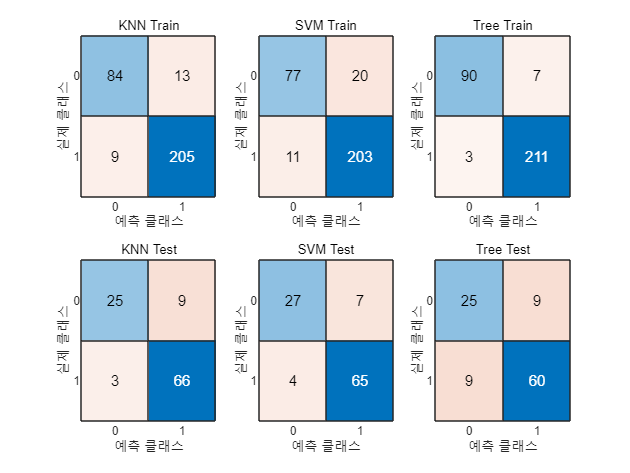

[Knn_Test_Loss_L, SVM_Test_Loss_L, Tree_Test_Loss_L] = KNN_SVM_TREE(Left_Train_Data, Left_Train_Label, Left_Test_Data, Left_Test_Label, 5);

### Classification Machine Learning about RIGHT dataset

KNN - SVM - TREE

k = 3

Knn_CrossValication_Error = 0.0629

Knn_Train_Loss = 0.0377

Knn_Test_Loss = 0.0282

SVM_CrossValication_Error = 0.0660

SVM_Train_Loss = 0.0314

SVM_Test_Loss = 0.0173

Tree_CrossValication_Error = 0.0566

Tree_Train_Loss = 0.0220

Tree_Test_Loss = 0.0380

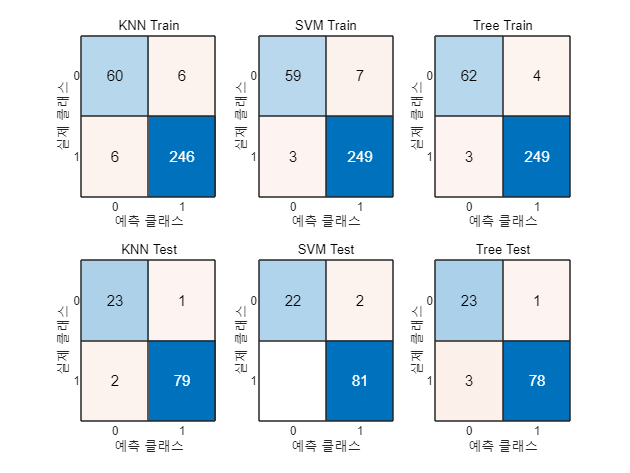

[Knn_Test_Loss_R, SVM_Test_Loss_R, Tree_Test_Loss_R] = KNN_SVM_TREE(Right_Train_Data, Right_Train_Label, Right_Test_Data, Right_Test_Label, 5);

## 3.7 Compare Accuracy Without Feature Selection

ColumnIndex_L     = 'Without_Selection_Accuracy_L';
ColumnIndex_R     = 'Without_Selection_Accuracy_R';
[Accuracy_Table_Without_Selection_L, Accuracy_Table_Without_Selection_R] = Evaluation_Accuracy(Knn_Test_Loss_L, SVM_Test_Loss_L, Tree_Test_Loss_L, ColumnIndex_L, Knn_Test_Loss_R, SVM_Test_Loss_R, Tree_Test_Loss_R, ColumnIndex_R);

Accuracy_Without_Selection_Table = [Accuracy_Table_Without_Selection_L Accuracy_Table_Without_Selection_R]

Accuracy_Without_Selection_Table = 3×2 table
            Without_Selection_Accuracy_L    Without_Selection_Accuracy_R
            ____________________________    ____________________________

    KNN                88.752                          97.179           
    SVM                 89.59                           98.27           
    Tree               82.769                            96.2           


# **4.    DTA/DLIP Lecture-Based Machine Learning with Sequential Feature Selection**

## 4.1 Sequential Feature Selection

### Sequential Feature Selection about LEFT dataset

[Left_Train_Data_select, Left_Test_Data_select, L_k_fold_accuracy, L_k_fold_accuracy_select, L_Loss_accuracy, L_Loss_accuracy_select] = Selection_SFS(Left_Train_Data,Left_Train_Label,Left_Test_Data,Left_Test_Label,5);

cv = K-겹 교차 검증 분할
   NumObservations: 311
       NumTestSets: 5
         TrainSize: 249  248  249  249  249
          TestSize: 62  63  62  62  62

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 7번 열 추가, 기준값 0.00272446
2단계, 2번 열 추가, 기준값 0.00259683
3단계, 5번 열 추가, 기준값 0.0022039
4단계, 6번 열 추가, 기준값 0.00217694
최종적으로 포함된 열: 2 5 6 7 


inmodel = 1×9 logical 배열
   0   1   0   0   1   1   1   0   0


history = 다음 필드를 포함한 struct :
      In: [4×9 logical]
    Crit: [0.0027 0.0026 0.0022 0.0022]


k_fold_accuracy = 0.8714

k_fold_accuracy_select = 0.8553

Loss_accuracy = 0.8684

Loss_accuracy_select = 0.8500

### Sequential Feature Selection about RIGHT dataset

[Right_Train_Data_select, Right_Test_Data_select, R_k_fold_accuracy, R_k_fold_accuracy_select, R_Loss_accuracy, R_Loss_accuracy_select] = Selection_SFS(Right_Train_Data,Right_Train_Label,Right_Test_Data,Right_Test_Label,5);

cv = K-겹 교차 검증 분할
   NumObservations: 318
       NumTestSets: 5
         TrainSize: 255  254  254  254  255
          TestSize: 63  64  64  64  63

순방향 순차적 특징 선택 시작:
포함된 초기 열: none
포함될 수 없는 열: none
1단계, 6번 열 추가, 기준값 0.00154643
2단계, 3번 열 추가, 기준값 0.000987351
3단계, 1번 열 추가, 기준값 0.000903876
최종적으로 포함된 열: 1 3 6 


inmodel = 1×9 logical 배열
   1   0   1   0   0   1   0   0   0


history = 다음 필드를 포함한 struct :
      In: [3×9 logical]
    Crit: [0.0015 9.8735e-04 9.0388e-04]


k_fold_accuracy = 0.9465

k_fold_accuracy_select = 0.9340

Loss_accuracy = 0.9816

Loss_accuracy_select = 0.9718

There is no significant difference in accuracy even if the feature is reduced.

As the result of applying the model to Test Dataset was the almost same as in train data, the direction of reducing the feature is correct for efficient learning.

## **4.2 Machine Learning with **Sequential Feature Selection

### Classification Machine Learning about LEFT dataset

KNN - SVM - TREE

k = 3

Knn_CrossValication_Error = 0.1158

Knn_Train_Loss = 0.0707

Knn_Test_Loss = 0.1432

SVM_CrossValication_Error = 0.1190

SVM_Train_Loss = 0.1061

SVM_Test_Loss = 0.1133

Tree_CrossValication_Error = 0.1383

Tree_Train_Loss = 0.0418

Tree_Test_Loss = 0.1707

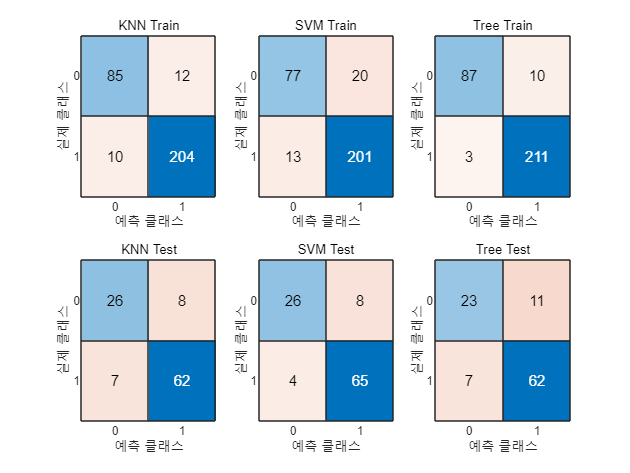

[Knn_Test_Loss_SFS_L, SVM_Test_Loss_SFS_L, Tree_Test_Loss_SFS_L] = KNN_SVM_TREE(Left_Train_Data_select, Left_Train_Label, Left_Test_Data_select, Left_Test_Label, 5);

### Classification Machine Learning about RIGHT dataset

KNN - SVM - TREE

k = 3

Knn_CrossValication_Error = 0.0535

Knn_Train_Loss = 0.0314

Knn_Test_Loss = 0.0184

SVM_CrossValication_Error = 0.0566

SVM_Train_Loss = 0.0314

SVM_Test_Loss = 0.0259

Tree_CrossValication_Error = 0.0566

Tree_Train_Loss = 0.0252

Tree_Test_Loss = 0.0380

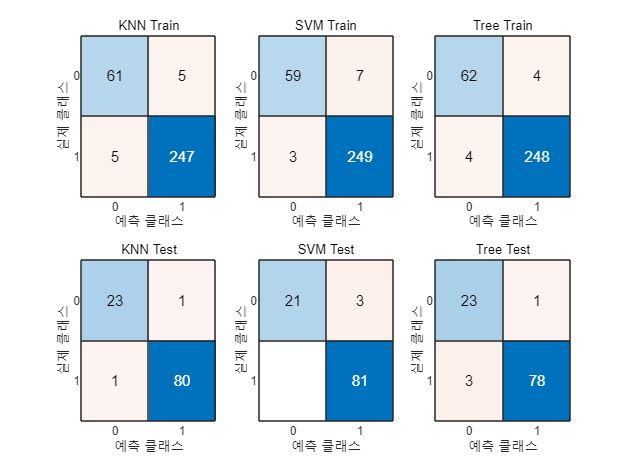

[Knn_Test_Loss_SFS_R, SVM_Test_Loss_SFS_R, Tree_Test_Loss_SFS_R] = KNN_SVM_TREE(Right_Train_Data_select, Right_Train_Label, Right_Test_Data_select, Right_Test_Label, 5);

## 4.3 Compare Accuracy with Sequential Feature Selection

ColumnIndex_L     = 'With_Sequential_Selection_Accuracy_L';
ColumnIndex_R     = 'With_Sequential_Selection_Accuracy_R';
[Accuracy_Table_With_Feature_Selection_L, Accuracy_Table_With_Feature_Selection_R] = Evaluation_Accuracy(Knn_Test_Loss_SFS_L, SVM_Test_Loss_SFS_L, Tree_Test_Loss_SFS_L, ColumnIndex_L, Knn_Test_Loss_SFS_R, SVM_Test_Loss_SFS_R, Tree_Test_Loss_SFS_R, ColumnIndex_R);

Accuracy_With_Sequential_Selection_Table = [Accuracy_Table_With_Feature_Selection_L Accuracy_Table_With_Feature_Selection_R]

Accuracy_With_Sequential_Selection_Table = 3×2 table
            With_Sequential_Selection_Accuracy_L    With_Sequential_Selection_Accuracy_R
            ____________________________________    ____________________________________

    KNN                     85.68                                  98.157               
    SVM                    88.672                                  97.406               
    Tree                   82.928                                    96.2               


# **5.    DTA/DLIP Lecture-Based Machine Learning with PCA**

## 5.1 Apply PCA

### PCA applied to LEFT dataset

[Left_Train_PCA_select, Left_Test_PCA_select, pcaCenter, coeff] = Selection_PCA(Left_Train_Data, Left_Test_Data);

explained =    87.4045
    8.9511
    2.2867
    1.0527
    0.3034
    0.0013
    0.0003
    0.0001
    0.0000


num = 2

As a result of PCA coefficient with 95% importance, it is confirmed that a total of 2 features can be used.

### PCA applied to RIGHT dataset

[Right_Train_PCA_select, Right_Test_PCA_select, pcaCenter, coeff] = Selection_PCA(Right_Train_Data, Right_Test_Data);

explained =    85.0973
    8.9047
    4.2529
    1.4250
    0.3182
    0.0012
    0.0005
    0.0002
    0.0000


num = 3

As a result of PCA coefficient with 95% importance, it is confirmed that a total of 3 features can be used.

## **5.2 Machine Learning with PCA**

### Classification Machine Learning about LEFT dataset

KNN - SVM - TREE

Left_Train_PCA_select  = array2table(Left_Train_PCA_select);
Left_Test_PCA_select   = array2table(Left_Test_PCA_select);

k = 3

Knn_CrossValication_Error = 0.1479

Knn_Train_Loss = 0.0932

Knn_Test_Loss = 0.1316

SVM_CrossValication_Error = 0.1543

SVM_Train_Loss = 0.1543

SVM_Test_Loss = 0.1133

Tree_CrossValication_Error = 0.1543

Tree_Train_Loss = 0.0514

Tree_Test_Loss = 0.1456

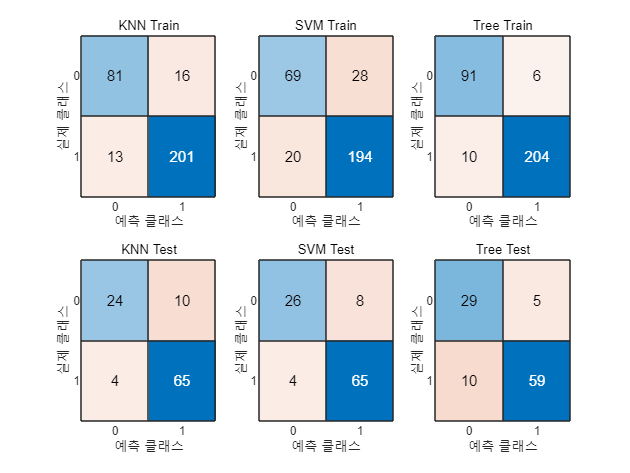

[Knn_Test_Loss_PCA_L, SVM_Test_Loss_PCA_L, Tree_Test_Loss_PCA_L] = KNN_SVM_TREE(Left_Train_PCA_select, Left_Train_Label, Left_Test_PCA_select, Left_Test_Label, 5);

### Classification Machine Learning about RIGHT dataset

KNN - SVM - TREE

Right_Train_PCA_select  = array2table(Right_Train_PCA_select);
Right_Test_PCA_select   = array2table(Right_Test_PCA_select);

k = 3

Knn_CrossValication_Error = 0.0503

Knn_Train_Loss = 0.0314

Knn_Test_Loss = 0.0184

SVM_CrossValication_Error = 0.0849

SVM_Train_Loss = 0.0503

SVM_Test_Loss = 0.0455

Tree_CrossValication_Error = 0.0786

Tree_Train_Loss = 0.0189

Tree_Test_Loss = 0.0380

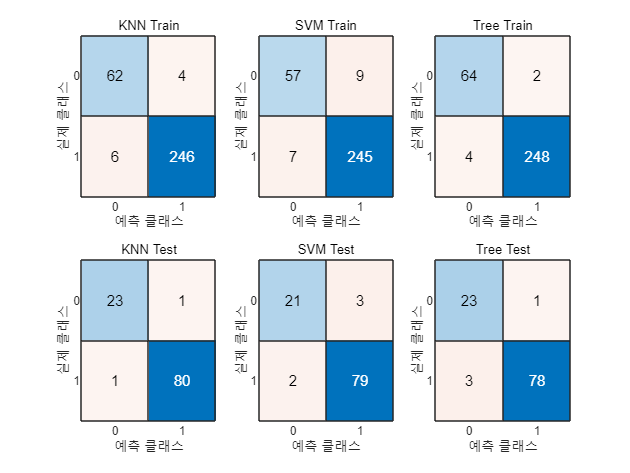

[Knn_Test_Loss_PCA_R, SVM_Test_Loss_PCA_R, Tree_Test_Loss_PCA_R] = KNN_SVM_TREE(Right_Train_PCA_select, Right_Train_Label, Right_Test_PCA_select, Right_Test_Label, 5);

## 5.3 Compare Accuracy with PCA

ColumnIndex_L     = 'With_PCA_Accuracy_L';
ColumnIndex_R     = 'With_PCA_Accuracy_R';
[Accuracy_Table_With_PCA_L, Accuracy_Table_With_PCA_R] = Evaluation_Accuracy(Knn_Test_Loss_PCA_L, SVM_Test_Loss_PCA_L, Tree_Test_Loss_PCA_L, ColumnIndex_L, Knn_Test_Loss_PCA_R, SVM_Test_Loss_PCA_R, Tree_Test_Loss_PCA_R, ColumnIndex_R);

Accuracy_With_PCA_Table = [Accuracy_Table_With_PCA_L Accuracy_Table_With_PCA_R]

Accuracy_With_PCA_Table = 3×2 table
            With_PCA_Accuracy_L    With_PCA_Accuracy_R
            ___________________    ___________________

    KNN           86.838                 98.157       
    SVM           88.672                 95.449       
    Tree          85.441                   96.2       


# **6.    Accuracy Compare & Model Evaluation**

### LEFT DATA

Accuracy_L = [Accuracy_Table_Guide_L, Accuracy_Table_Without_Selection_L, Accuracy_Table_With_Feature_Selection_L, Accuracy_Table_With_PCA_L]

Accuracy_L = 3×4 table
            GuideBook_Accuracy_L    Without_Selection_Accuracy_L    With_Sequential_Selection_Accuracy_L    With_PCA_Accuracy_L
            ____________________    ____________________________    ____________________________________    ___________________

    KNN            93.122                      88.752                               85.68                         86.838       
    SVM            83.183                       89.59                              88.672                         88.672       
    Tree           83.999                      82.769                              82.928                         85.441       


### RIGHT DATA

Accuracy_R = [Accuracy_Table_Guide_R, Accuracy_Table_Without_Selection_R Accuracy_Table_With_Feature_Selection_R Accuracy_Table_With_PCA_R]

Accuracy_R = 3×4 table
            GuideBook_Accuracy_R    Without_Selection_Accuracy_R    With_Sequential_Selection_Accuracy_R    With_PCA_Accuracy_R
            ____________________    ____________________________    ____________________________________    ___________________

    KNN            95.303                      97.179                              98.157                         98.157       
    SVM            87.377                       98.27                              97.406                         95.449       
    Tree           93.098                        96.2                                96.2                           96.2       


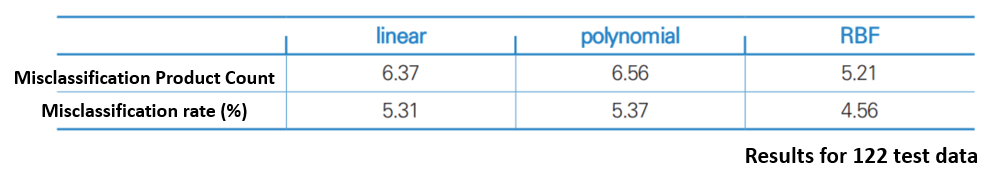

In the guidebook, SVM was applied to preprocessed data{Right Dataset), and accuracy of **95.44%** was shown **for RBF SVM.**

On the other hand, when KNN, SVM, and Decision Tree were applied to the preprocessed data{Right Dataset) presented in the guidebook, the accuracy of **95.3%** was shown **in KNN.**

Meanwhile, for the preprocessed data{Right Dataset) we performed for this project, we showed a high accuracy of **98.27% in Gaussian SVM.**

That is, it may be determined that an injection molding machine defect diagnosis algorithm has been successfully implemented.

# **7. Flow Chart**

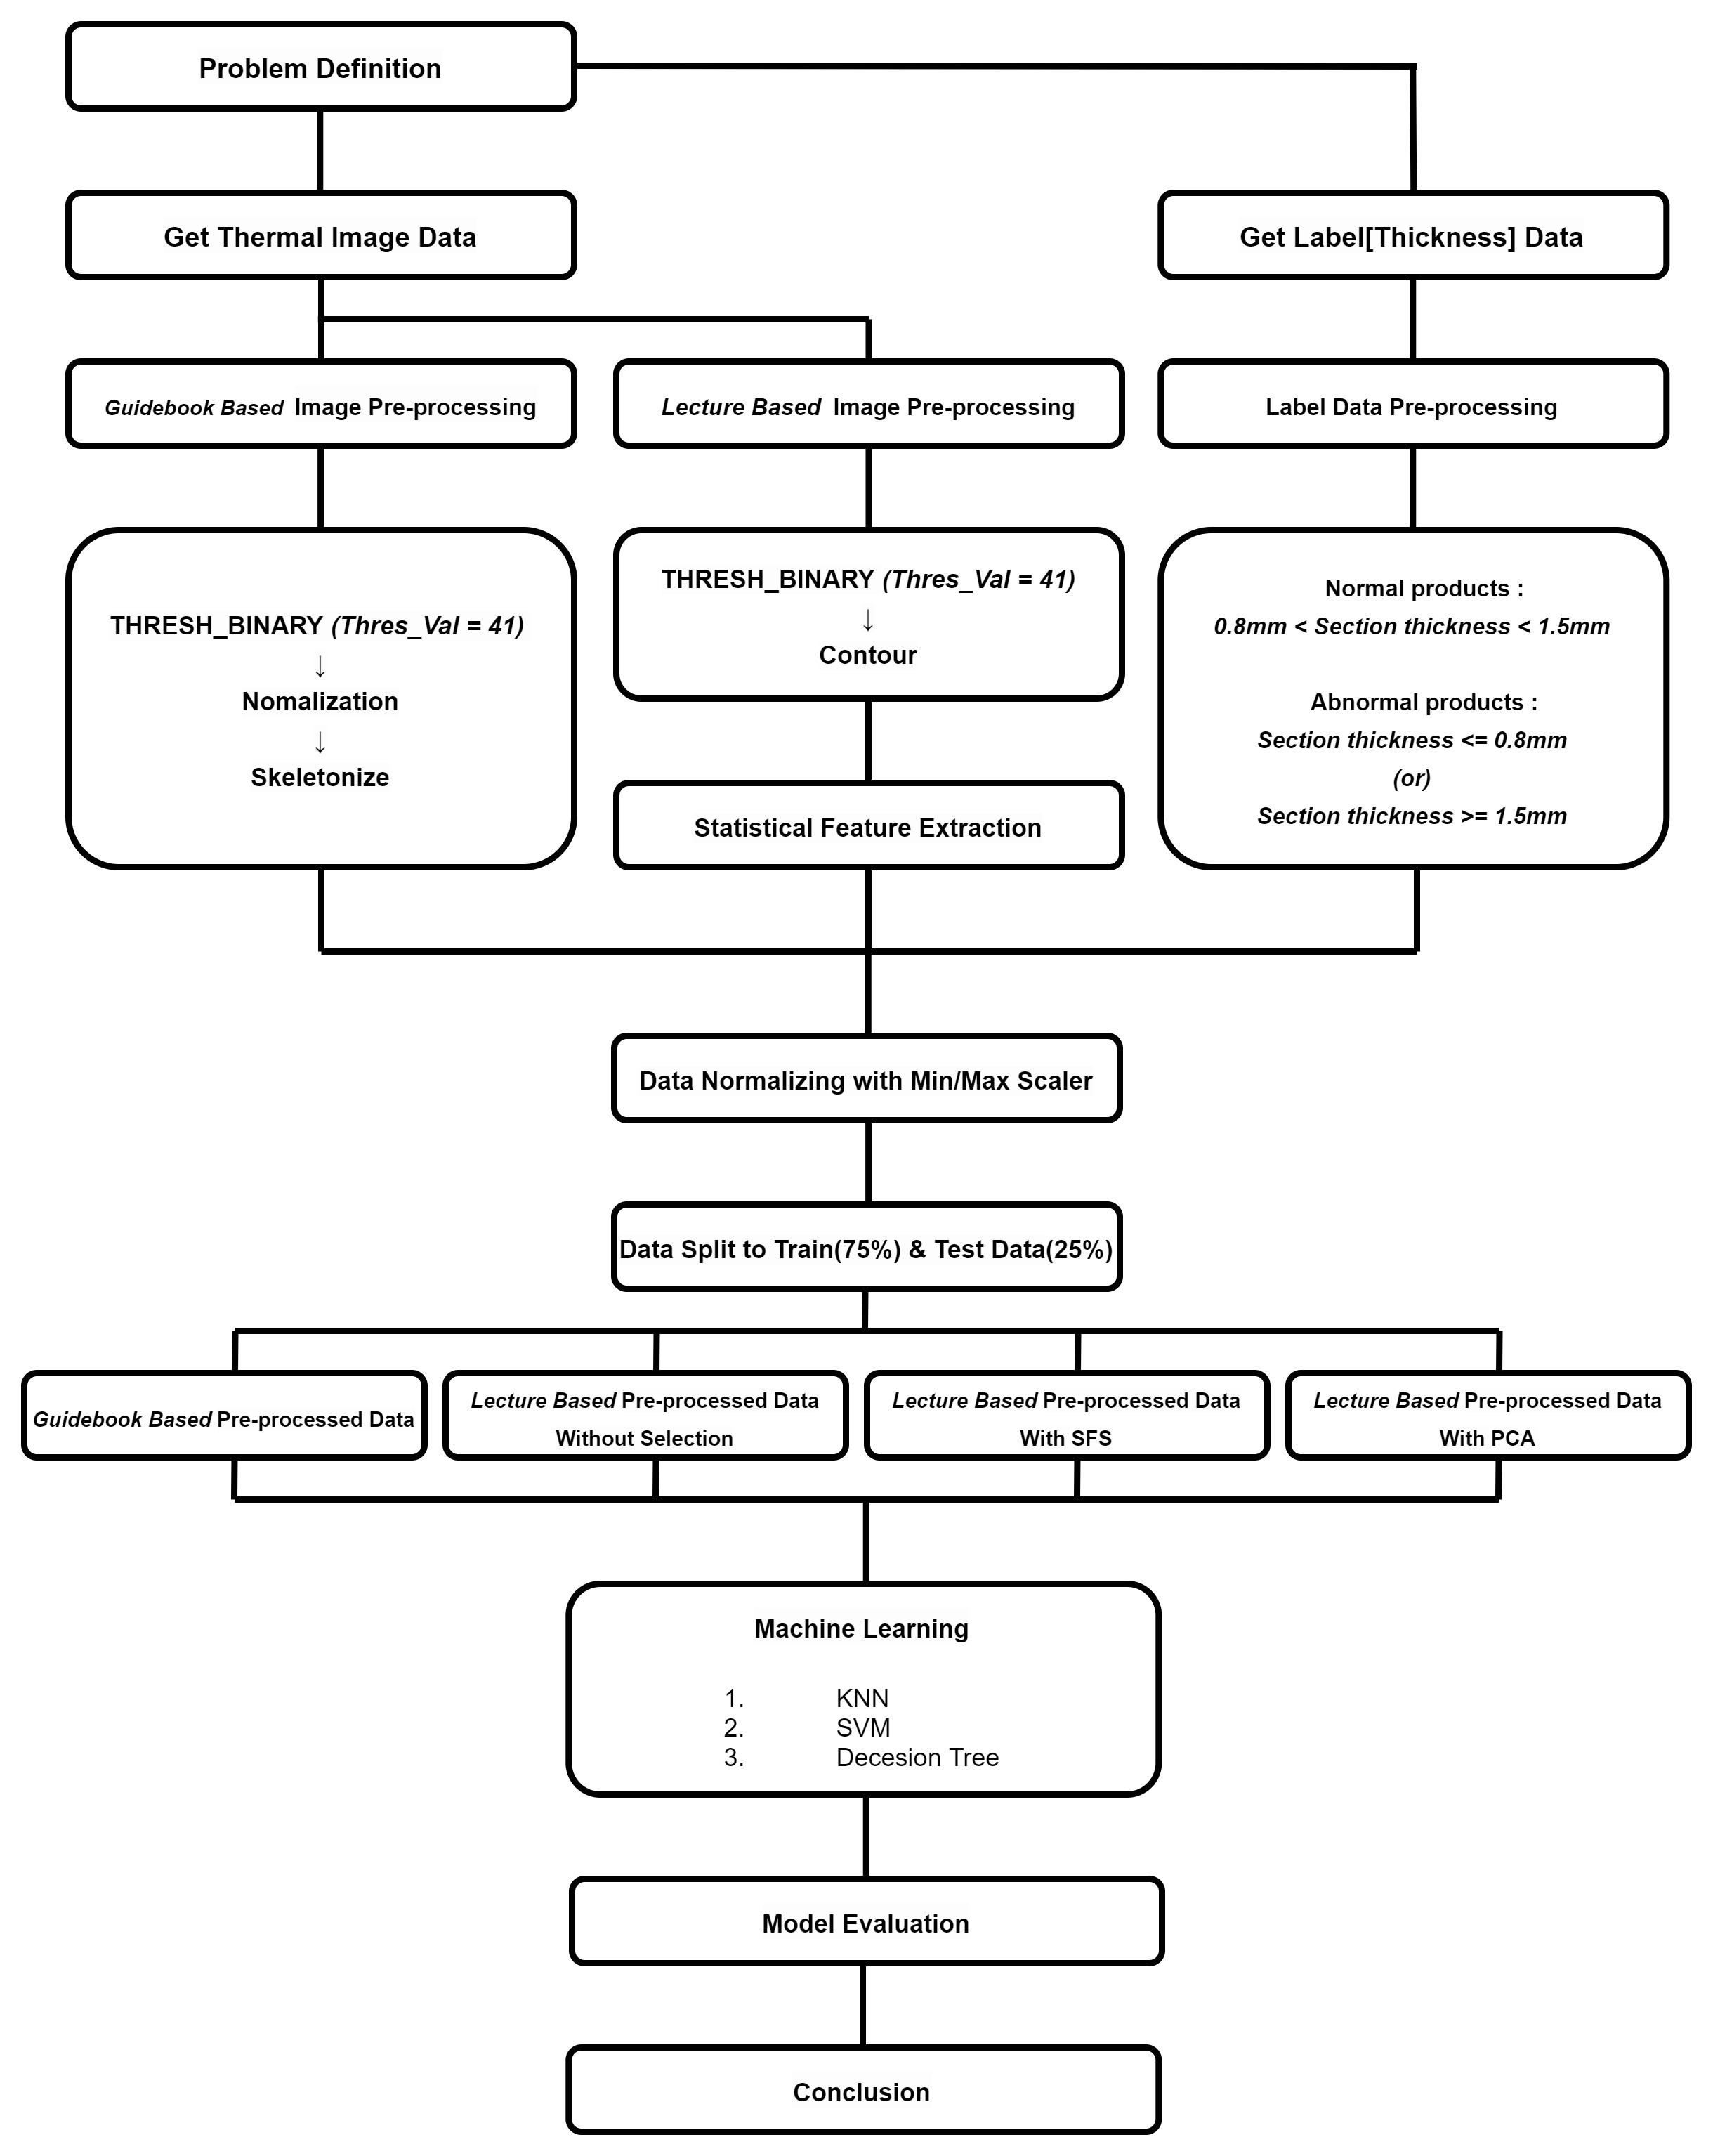

# **8. Discussion & Conclusion**

### Discussion

In the guidebook, the model learning process for the provided preprocessed data was not disclosed in detail. Therefore, the accuracy was confirmed by applying the KNN, SVM, and Decision Tree Model that we have studied during this semester. As a result, when KNN was applied, a high accuracy of 95.3% was confirmed. This was similar to the best accuracy of 95.44% presented in the guidebook. Therefore, it was possible to determine that the preprocessed data provided in the guidebook was quite good data.

After verifying the preprocessed data provided in the guidebook, we performed feature extraction by preprocessing the thermal image data in our own way. And we applied KNN, SVM, and Decision Tree Model to this data. Subsequently, the classification accuracy was compared before and after Feature Selection. As a result, for the Right Dataset, it showed a high accuracy of 98.27% when Gaussian SVM. For the Left Dataset, the Gaussian SVM showed a relatively good accuracy of 89.59%.

Therefore, it may be determined that an injection molding machine defect diagnosis algorithm has been successfully implemented.

Additionally, we were able to think a lot about which feature is reasonable to use while conducting the injection molding product defect diagnosis project.

And especially, we could think about the importance of selecting models. When SVM was applied, the accuracy was relatively poor. However, due to the characteristics of the data, the temperature of the abnormal data is relatively high or low, so it can be regarded as an outlier. In addition, based on the fact that there are more normal data compared to abnormal data, the distribution of the data was judged to be Gaussian. Therefore, we applied Gaussian SVM and we confirmed good accuracy.

### Conclusion

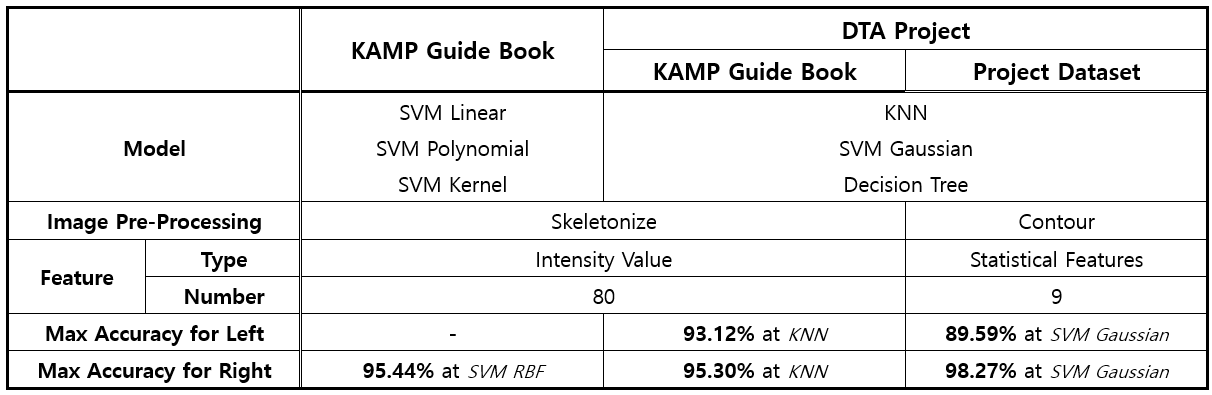

Statistical features were extracted for data preprocessed with 'THRESH_BINARY' and 'CONTOUR'. Since then, as a result of learning with 'Gaussian SVM', 98.27% of accuracy, which is 2.83% higher than that of the guidebook, which showed 95.44% accuracy for 'Right Data'.

On the other hand, for Left Data, the accuracy of 89.59% was confirmed as a result of learning with Gaussian SVM. However, the guidebook did not disclose the classification accuracy for Left Data, so there was no indicator to compare with the 89.59%. Therefore, KNN, SVM, and Decision Tree were applied to the data presented in the guidebook, and 93.12% accuracy was confirmed in KNN. In other words, in the case of Left Data, it was judged that the performance was slightly lower than the preprocessed data provided in the guidebook, but nevertheless, it showed good classification accuracy close to 90%.

# **9. Reference**

**[1]    **KAMP, 제조 AI 데이터셋, 머신비전 AI 데이터셋, 열화상 이미지를 이용한 양/불량 판정을 위한 머신비전 데이터, KAIST, 2020.12.14, click [here](https://www.kamp-ai.kr/front/dataset/AiDataDetail.jsp?AI_SEARCH=&page=1&DATASET_SEQ=6&EQUIP_SEL=&FILE_TYPE_SEL=&GUBUN_SEL=&WDATE_SEL=)